clc
clear

% Import the data from .csv file
[t, toy, p, Ws1, Wd1, T1, Ws2, Wd2, T2, Ws3, Wd3, T3] = ...
    importfile('cex4WindDataInterpolated.csv');

% Retain only valid data
p_valid = p(~isnan(p));
Ws1_valid = Ws1(~isnan(p));
p_valid = p_valid(~isnan(Ws1_valid));
Ws1_valid = Ws1_valid(~isnan(Ws1_valid));

output_input =

Time domain data set with 36287 samples.
Sample time: 1 seconds                   
                                         
Outputs      Unit (if specified)         
   y1                                    
                                         
Inputs       Unit (if specified)         
   u1                                    
                                         


% Create output-input object
output_input = iddata(p_valid,Ws1_valid,1)

% Define the number of parameters
na = 4;  % AR part
nb = 4;  % AR part on inputs
nc = 0;  % MA part
nk = 0;  % Delay on inputs

sys =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)               
  A(z) = 1 - 1.037 z^-1 + 0.1868 z^-2 - 0.0675 z^-3 + 0.02888 z^-4
                                                                  
  B(z) = 0.2521 - 0.06041 z^-1 - 0.02968 z^-2 - 0.08843 z^-3      
                                                                  
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=0
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                  
Estimated using ARMAX on time domain data "output_input".
Fit to estimation data: 71.5% (prediction focus)         
FPE: 2.454, MSE: 2.453                                   


% Fit the model
sys = armax(output_input,[na nb nc nk])

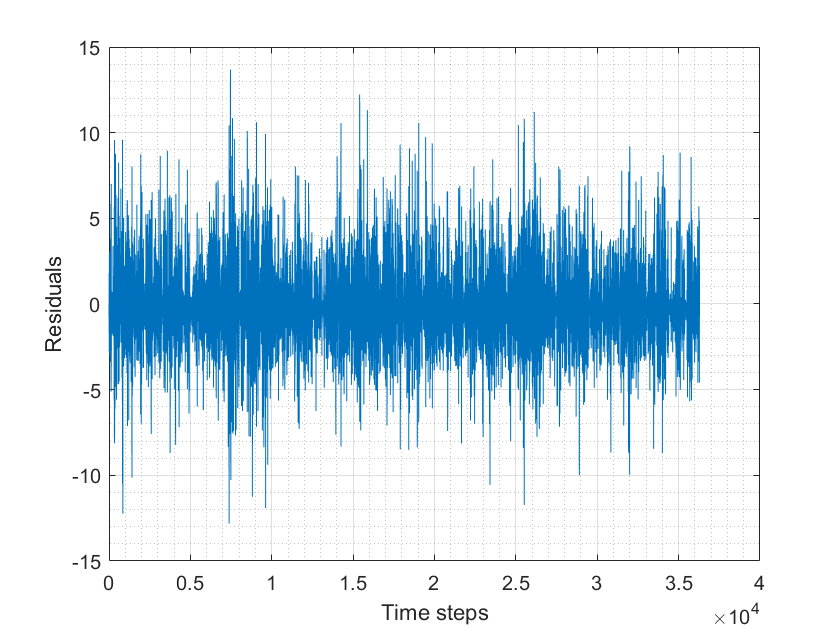

% Get residuals
res1 = resid(sys,output_input).y(:,1);
plot(res1)
grid on; grid minor;
xlabel('Time steps')

ylabel('Residuals')

% Ljung-Box test

h = 1×10 logical array
   0   0   1   1   1   1   0   0   0   0


pvalues =     0.3210    0.1353    0.0133    0.0223    0.0198    0.0325    0.0537    0.0851    0.0983    0.1365


[h,pvalues]=lbqtest(res1,'lags',[1,2,3,4,5,6,7,8,9,10])
% The residuals are clearly correlated

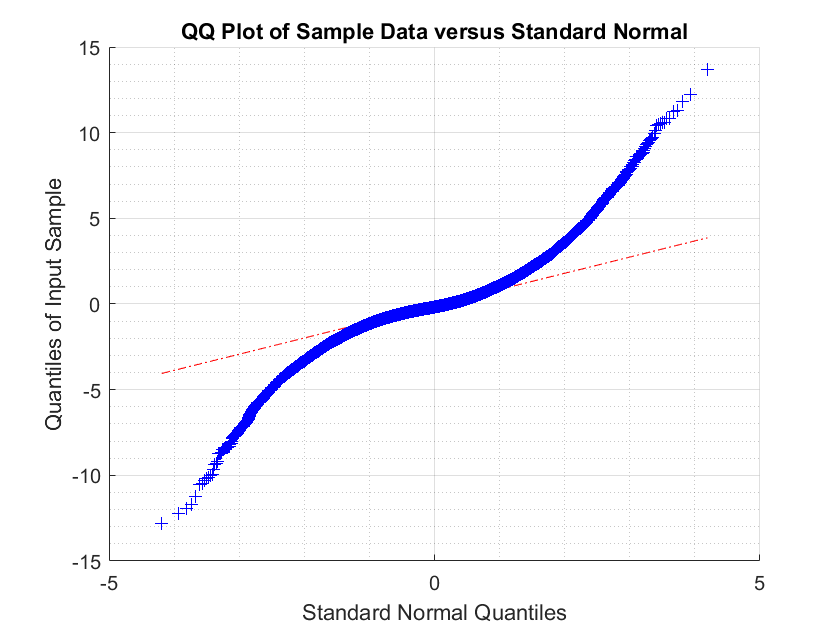

%Histogram of residuals
histogram(res1,50)
grid on; grid minor;
xlabel('Residuals')
ylabel('Count')

%QQ plot
qqplot(res1)
grid on; grid minor;

% Sign test
count=0;
for i=1:length(res1)-1
    if sign(res1(i)) == sign(res1(i+1))
        count = count+1;
    end
end
percent_sign_change = count/length(res1)

percent_sign_change = 0.5862


%The number of sign changes is not between 40 and 60%
%This is not white noise

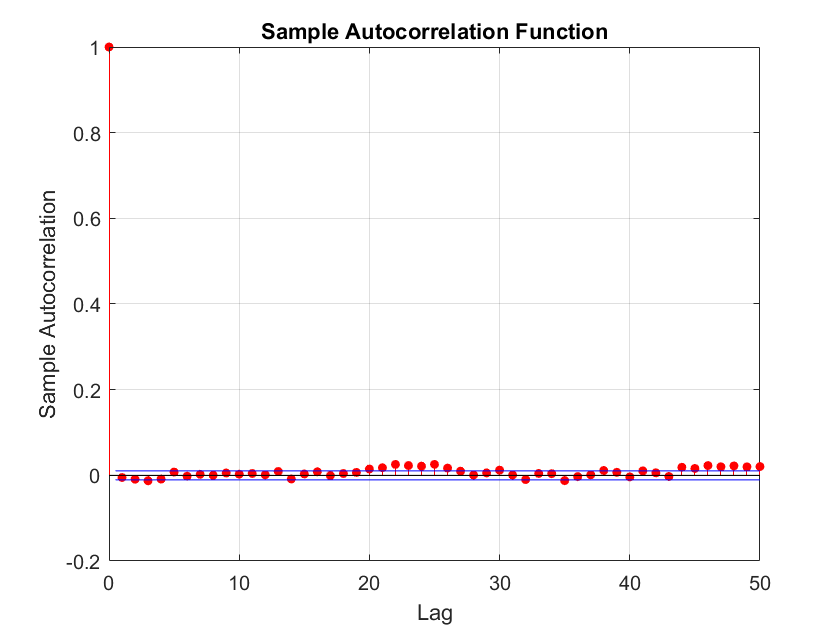

% ACF and PACF of the residuals
autocorr(res1,'NumLags',50)

parcorr(res1,'NumLags',50)

**Predictions 1, 2 and 3 hours ahead with ARMAX(4,4,0)**

error = zeros(length(p_valid)-7,3);
for i=4:length(p_valid)-3
    % Prediction 3h ahead given past data
    p_hat = forecast(sys,output_input(1:i),3,output_input(i+1:i+3));
    error(i-3,:) = p_hat.y - p_valid(i+1:i+3);
    if mod(i,400)==0
        X = sprintf('Compute %d%%',round(100*i/(length(p_valid)-7)));
        disp(X)
    end
end

Compute 1%
Compute 2%
Compute 3%
Compute 4%
Compute 6%
Compute 7%
Compute 8%
Compute 9%
Compute 10%
Compute 11%
Compute 12%
Compute 13%
Compute 14%
Compute 15%
Compute 17%
Compute 18%
Compute 19%
Compute 20%
Compute 21%
Compute 22%
Compute 23%
Compute 24%
Compute 25%
Compute 26%
Compute 28%
Compute 29%
Compute 30%
Compute 31%
Compute 32%
Compute 33%
Compute 34%
Compute 35%
Compute 36%
Compute 37%
Compute 39%
Compute 40%
Compute 41%
Compute 42%
Compute 43%
Compute 44%
Compute 45%
Compute 46%
Compute 47%
Compute 49%
Compute 50%
Compute 51%
Compute 52%
Compute 53%
Compute 54%
Compute 55%
Compute 56%
Compute 57%
Compute 58%
Compute 60%
Compute 61%
Compute 62%
Compute 63%
Compute 64%
Compute 65%
Compute 66%
Compute 67%
Compute 68%
Compute 69%
Compute 71%
Compute 72%
Compute 73%
Compute 74%
Compute 75%
Compute 76%
Compute 77%
Compute 78%
Compute 79%
Compute 80%
Compute 82%
Compute 83%
Compute 84%
Compute 85%
Compute 86%
Compute 87%
Compute 88%
Compute 89%
Compute 90%
Compute 92%
Compute 93%


% RMSE for each step ahead
RMSE_1h = sqrt(mean(error(:,1).^2))

RMSE_1h = 1.5663

RMSE_2h = sqrt(mean(error(:,2).^2))

RMSE_2h = 2.2524

RMSE_3h = sqrt(mean(error(:,3).^2))

RMSE_3h = 2.6385


% 95% confidence intervals
CI_1h = [RMSE_1h*norminv(0.025),RMSE_1h*norminv(0.975)]

CI_1h =    -3.0699    3.0699


CI_2h = [RMSE_2h*norminv(0.025),RMSE_2h*norminv(0.975)]

CI_2h =    -4.4147    4.4147


CI_3h = [RMSE_3h*norminv(0.025),RMSE_3h*norminv(0.975)]

CI_3h =    -5.1713    5.1713
